# ECSE 343: Numerical Methods

## Newton-Raphson Method

Suppose we want to find the solution for the fololowing equation,

                                    
$$xe^x-2 =0$$


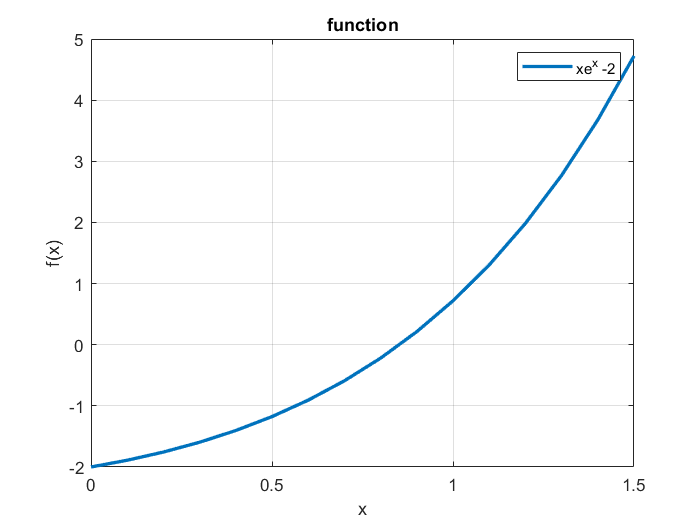

f =@(x) x.*exp(x)-2;
x = 0:0.1:1.5;
figure()
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
title('function')
xlabel('x')
ylabel('f(x)')
legend 
grid on 

% fplot(f,[0 1.5])

We can see on the graph that the root is near x=1, so we can use that as our intial guess. Note that in practical situations it is not possible to plot the function as it may be very costly to evaluate the function at many inputs and/or the function may be a multdimenisional function. In practice the initial guess is chossen  using heuristics and it depends on the problem we are trying to solve.

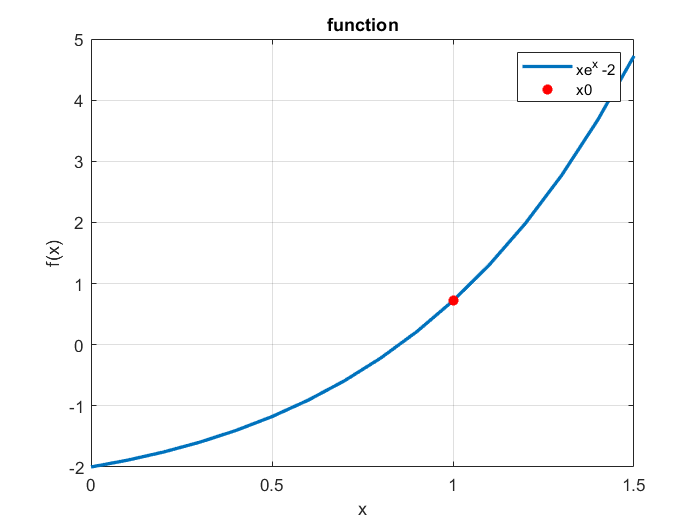

x0 = 1; %intial guess
fx0 = f(x0);
figure()
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
hold on 
plot(fx0, 'r*', 'LineWidth',2,'DisplayName','x0')
title('function')
xlabel('x')
ylabel('f(x)')
legend 
grid on 

Next we comute the derivative of the function, $f(x)$

  
$$f(x) = xe^x-2 $$



$$f'(x) = (x + 1 ) e^x$$


Now we use the derivative of the function $f(x)$ to LINEARIZE the function at the point $(x_0, f(x_0) )$.


$$f(x) = f(x_0) + f'(x_0) (x-x_0) +\frac{1}{2} f''(x_0) (x-x_0) ^2  +\frac{1}{3!} f'''(x_0) (x-x_0) ^3 +....$$


We consider the first two terms and label it as,


$$l_0(x) = f(x_0) + f'(x_0) (x-x_0)$$


where $l_0(x)$ denotes the linearised $f(x)$ at $x_0$

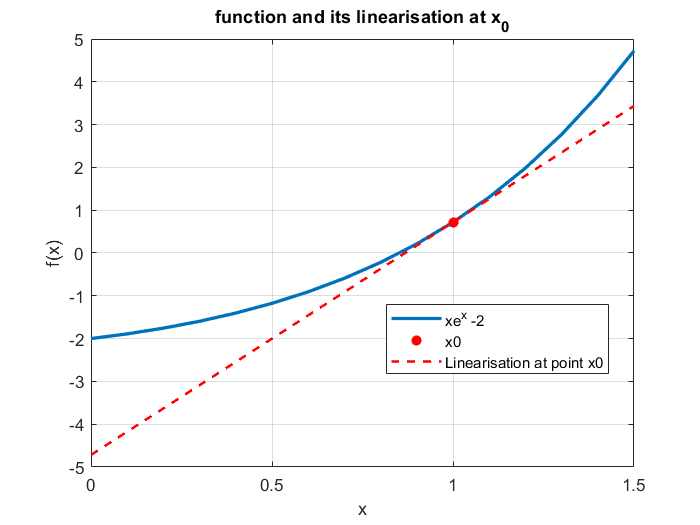

dfdx =@(x) (x+1).*exp(x);    % this is the deriivative of f(x)

slope0= dfdx(x0);

l_x0 = @(x) f(x0) + slope0*(x-x0);   %linerisation_at_x0

figure()
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
hold on 
plot(fx0, 'r*', 'LineWidth',2,'DisplayName','x0')
plot(x,l_x0(x), 'r--', 'LineWidth',1.5,'DisplayName','Linearisation at point x0')

title('function and its linearisation at x_0')
xlabel('x')
ylabel('f(x)')
legend('Location',"best")
grid on 

Finding the root/solution of $f(x)$ is very difficult. Instead it is trivial to find the root of linearised function, $l_0(x)$,


$$l_0(x) = 0$$


i.e., $ f(x_0) + f'(x_0) (x-x_0)=0$

Rearranging the above equation we get,


$$x =x_0 -\frac{ f(x_0)}{f'(x_0)}$$


This solution/root of the linearised function $l_0(x)$ then becomes our NEXT guess.  

Note that in practice the linearisation function $l_0(x)$ is NOT compute explicitly instead we directly use,$x =x_0 -\frac{ f(x_0)}{f'(x_0)}$ to compute the next guess.

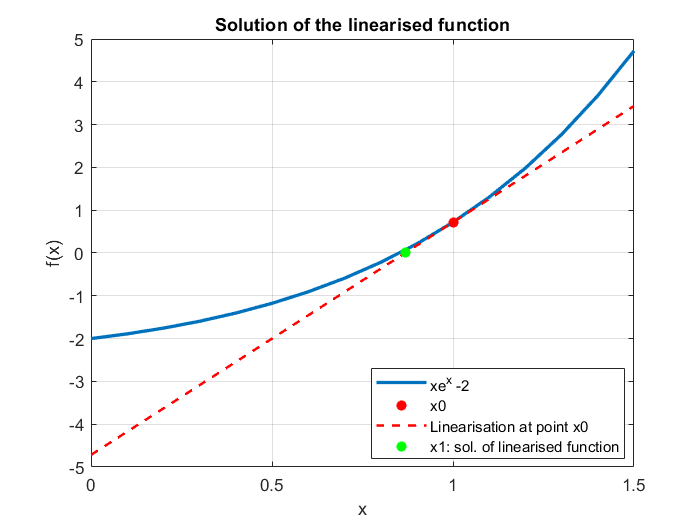

% compute the solution for our linearisation of the function at x0.

x1 = x0 - f(x0)/dfdx(x0);  % this x1 is our next intial guess.
% x1 is the solution of the linearised function. 



figure()
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
hold on 
plot(fx0, 'r*', 'LineWidth',2,'DisplayName','x0')
plot(x,l_x0(x), 'r--', 'LineWidth',1.5,'DisplayName','Linearisation at point x0')

plot(x1,0, 'g*', 'LineWidth',2,'DisplayName','x1: sol. of linearised function')
title('Solution of the linearised function')
xlabel('x')
ylabel('f(x)')
legend('Location',"best")
grid on 

The value of $f(x)$ at $x_1$ is not zero but it is smaller than its value at $x_0$, therefore, we repeat the above process. This time we will use $x_1$ as the initial guess.

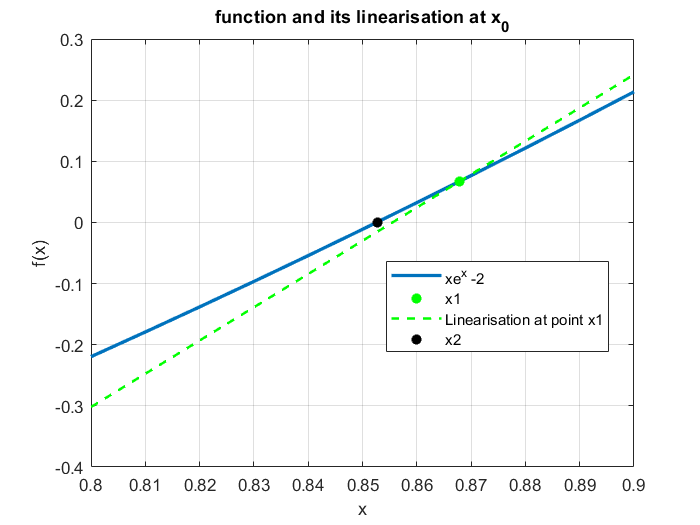

x = 0.8:0.01:0.9;
l_x1= @(x) f(x1) + slope0*(x-x1);   %linerisation_at_x1  
% (IN PRACTICE THIS IS NEVER COMPUTED  EXPLICITLLY)/

x2 = x1 - f(x1)/dfdx(x1);
                                    

figure()
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
hold on 
plot(x1,f(x1), 'g*', 'LineWidth',2,'DisplayName','x1')
plot(x,l_x1(x), 'g--', 'LineWidth',1.5,'DisplayName','Linearisation at point x1')
plot(x2,0, 'k*', 'LineWidth',2,'DisplayName','x2')
title('function and its linearisation at x_0')
xlabel('x')
ylabel('f(x)')
legend('Location',"best")
grid on 

## Newton-Raphson Example  #2 

One of the problems with Newton-Raphson is that it needs a "good" initial guess for it to converge to the solution quickly. The "good" initial guess refers to a initial guess which is closer to the orignal solution.

The good initial guess is often chossen using the knowledge of the problem.

To demonstrate this 

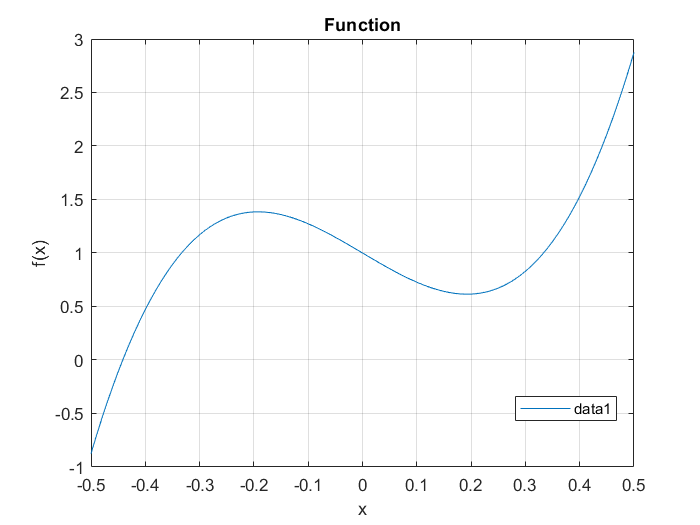

f = @(x)27*x.^3-3*x + 1;
dfdx =@(x) 81*x.^2-3;
x = -0.5:0.01:0.5;

% x = -100*pi:0.1:100*pi;
% f = @(x) atan(x);
% dfdx = @(x) 1./ ( (1+x.^2).^2 );
figure
plot(x,f(x))
xlabel('x')
ylabel('f(x)')
legend('Location',"best")
title("Function")
grid on 

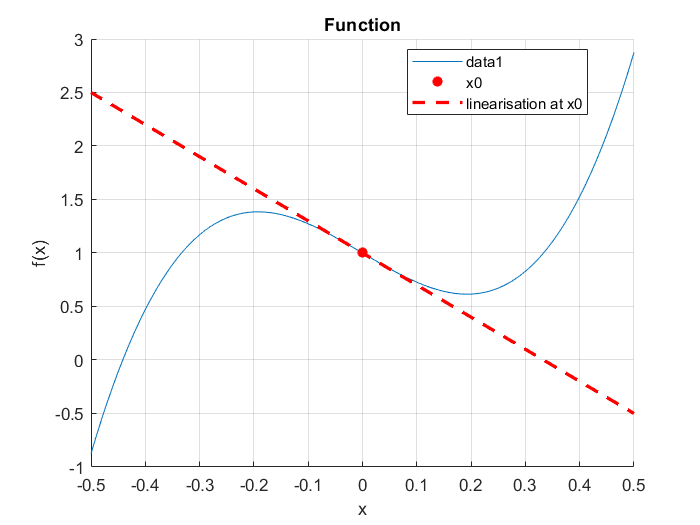

x0 = 0;
% linearisation of f(x) at x0
l_x0 = @(x) f(x0) + dfdx(x0)*(x-x0);
figure
hold on
plot(x,f(x))
plot(x0,f(x0), 'r*', 'LineWidth',2,'DisplayName','x0')
plot(x,l_x0(x), 'r--', 'LineWidth',2,'DisplayName','linearisation at x0')
xlabel('x')
ylabel('f(x)')
legend('Location',"best")
title("Function")
grid on 

Next we find the solution of the linearised funciton,

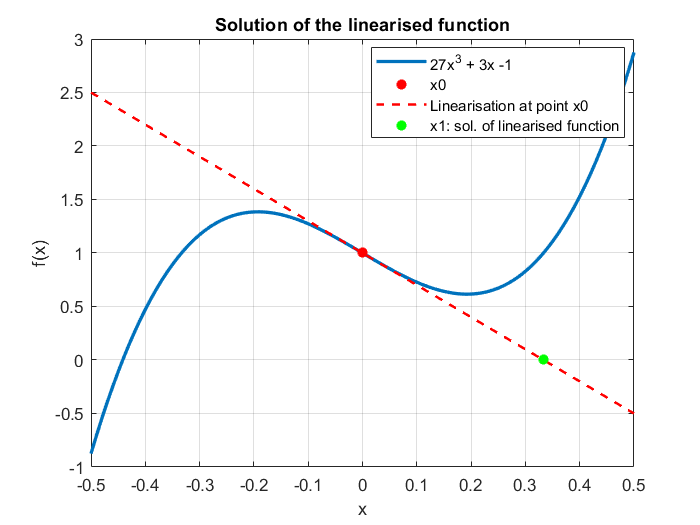

x1 = x0 -f(x0)/dfdx(x0); 
figure()
plot(x,f(x), 'LineWidth',2,'DisplayName','27x^3 + 3x -1')
hold on 
plot(x0,f(x0), 'r*', 'LineWidth',2,'DisplayName','x0')
plot(x,l_x0(x), 'r--', 'LineWidth',1.5,'DisplayName','Linearisation at point x0')

plot(x1,0, 'g*', 'LineWidth',2,'DisplayName','x1: sol. of linearised function')
title('Solution of the linearised function')
xlabel('x')
ylabel('f(x)')
legend('Location',"best")
grid on 

Since the value of the function ar x1 is not zero, repeat our process.

x = -1:0.01:2;
% x = 100*pi:0.1:100*pi;
figure()
xinit = x1;
while abs(f(xinit))>1e-4
clf("reset")
l_xinit = @(x) f(xinit) + dfdx(xinit)*(x-xinit);
xnew = xinit -f(x0)/dfdx(xinit); 

plot(x,f(x), 'LineWidth',2,'DisplayName','27x^3 + 3x -1')
hold on 
plot(xinit,f(xinit), 'r*', 'LineWidth',2,'DisplayName','x0')
plot(x,l_xinit(x), 'r--', 'LineWidth',1.5,'DisplayName','Linearisation at point x0')

plot(xnew,0, 'g*', 'LineWidth',2,'DisplayName','x1: sol. of linearised function')
xlabel('x')
ylabel('f(x)')
legend('Location',"best")
grid on 
% iter = iter +1;

title(['Sol. of the linearised system, x=' num2str(xnew)])

xinit = xnew;
pause(1)
end

## Secant  Method

One of the problems with Newton Rapshon method is the availability of derivative, $f'(x)$. The secant method overcomes this difficulty by using the approximation of the derivative.

Let's return to our probem, $xe^x-2 =0$ 

f =@(x) x.*exp(x)-2;
x = 0:0.1:1.5;
figure()
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
title('function')
xlabel('x')
ylabel('f(x)')
legend 
grid on 

We can see that the root lies between $x=0.5$ and $x=1$.

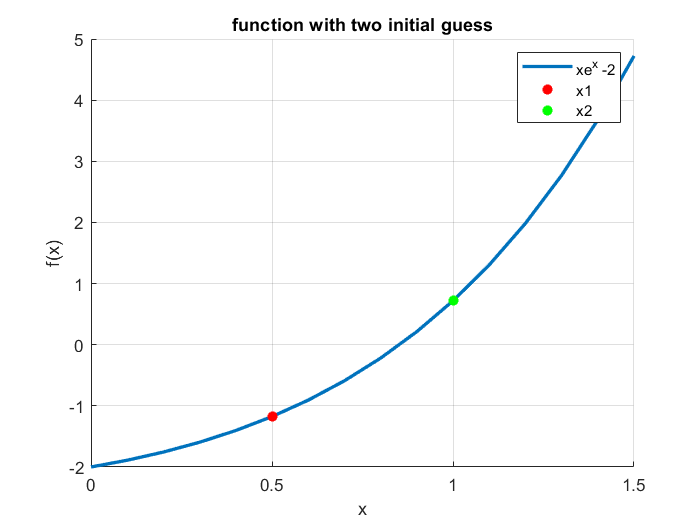

x1 = 0.5;
f1 = f(x1);
x2 = 1;
f2 = f(x2);

figure
hold on
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
plot(x1,f(x1),'r*','LineWidth',2,'DisplayName','x1')
plot(x2,f(x2),'g*','LineWidth',2,'DisplayName','x2')
title('function with two initial guess')
xlabel('x')
ylabel('f(x)')
legend 
grid on 

Using  these $x_1$ and $x_2$ as initial guesses, we can approximate the value of the derivative of $f(x)$ as,

                                        
$$f'(x) \approx \frac{f(x_2)-f(x_1)}{x_2 - x_1}$$


We can use the approximated value of the derivative to linearise the funtion, $f(x)$,


$$s_2(x) = f(x_2) + \left( \frac{f(x_2)-f(x_1)}{x_2 - x_1}  \right)  (x-x_2)$$


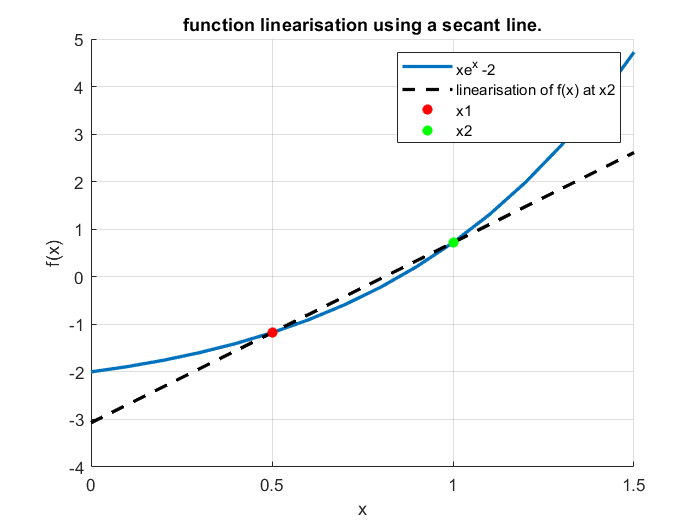

dfdx_approx = ( f(x2)-f(x1) )/ (x2 - x1);
s2 = @(x) f(x2) + dfdx_approx*(x-x2);

figure
hold on
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
plot(x,s2(x),'k--','LineWidth',2,'DisplayName','linearisation of f(x) at x2')
plot(x1,f(x1),'r*','LineWidth',2,'DisplayName','x1')
plot(x2,f(x2),'g*','LineWidth',2,'DisplayName','x2')
title('function linearisation using a secant line.')
xlabel('x')
ylabel('f(x)')
legend 
grid on 

Using the same strategy of as Newton-Rapshon method, we can find the solution of the secant approximation, i.e. find $x$ such that $s_2(x) = 0$.


$$ f(x_2) + \left( \frac{f(x_2)-f(x_1)}{x_2 - x_1}  \right)  (x-x_2) = 0$$


On rearranging  we get,


$$x = x_2 -\frac{f(x_2)}{f'_{approx}} $$


where $f'_{approx}$ is the approximation of the derivative of  $f(x)$.

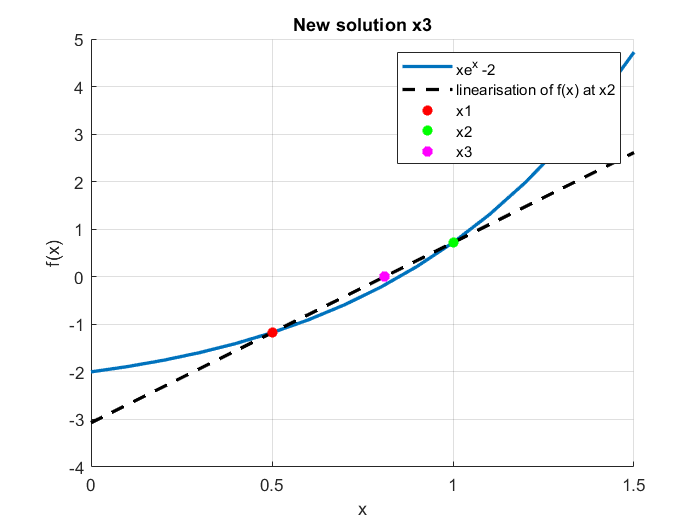

x3 = x2 - f(x2)/dfdx_approx;   

figure
hold on
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
plot(x,s2(x),'k--','LineWidth',2,'DisplayName','linearisation of f(x) at x2')
plot(x1,f(x1),'r*','LineWidth',2,'DisplayName','x1')
plot(x2,f(x2),'g*','LineWidth',2,'DisplayName','x2')
plot(x3,0,'m*','LineWidth',3,'DisplayName','x3')
title('New solution x3')
xlabel('x')
ylabel('f(x)')
legend 
grid on 

The value of $f(x)$ at $x_3$ is not zero but it is smaller than its value at $x_2$. Therefore, we need to repeat the above process again using the two most recent points $x_2$ and $x_3$

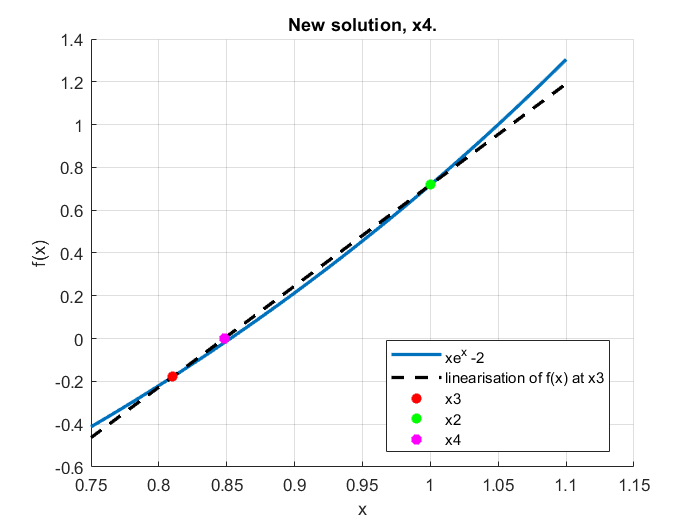

x = 0.75:0.01:1.1;
dfdx_approx = ( f(x3)-f(x2) )/ (x3 - x2);
s3 = @(x) f(x3) + dfdx_approx*(x-x3);

x4 = x3 - f(x3)/dfdx_approx;   

figure
hold on
plot(x,f(x), 'LineWidth',2,'DisplayName','xe^x -2')
plot(x,s3(x),'k--','LineWidth',2,'DisplayName','linearisation of f(x) at x3')
plot(x3,f(x3),'r*','LineWidth',2,'DisplayName','x3')
plot(x2,f(x2),'g*','LineWidth',2,'DisplayName','x2')
plot(x4,0,'m*','LineWidth',3,'DisplayName','x4')
title('New solution, x4.')
xlabel('x')
ylabel('f(x)')
legend("Location","best") 
grid on 